% Numerator and denominator of the transfer function
num = [7e-5 7e-5 0.11 0.95];
denom = [7.2e-5 1.44e-4 0.12 8.2 8.08];

% The transfer function
system = tf(num, denom);

% Margins and bode diagram
[Gain_margin, phase_margin, Wfpc, Wacf] = margin(system);

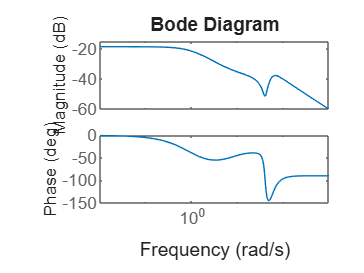


% Bode diagram
figure;
bode(system);
title('Bode Diagram');



fprintf('Gain Margin (in dB): %.2f dB\n', 20 * log10(Gain_margin));

Gain Margin (in dB): Inf dB


fprintf('Phase Margin: %.2f degrees\n', phase_margin);

Phase Margin: Inf degrees


fprintf('Frequency of Phase Crossing : %.2f rad/s\n', Wfpc);

Frequency of Phase Crossing (rad/s): NaN rad/s


fprintf('Frequency of Amplitude Crossing : %.2f rad/s\n', Wacf);

Frequency of Amplitude Crossing (rad/s): NaN rad/s




Gain_margin_dB = 20 * log10(Gain_margin)

Gain_margin_dB = Inf


% Stability analysis based on margins
if Gain_margin_dB > 0 && phase_margin > 0
    disp('The system is stable.');
else
    disp('The system is unstable.');
end

The system is stable.
